b) Find optimal p

A = [1,1; 0,1];
b = [0.5; 1];

A_bar = [A^9*b, A^8*b, A^7*b, A^6*b, A^5*b, A^4*b, A^3*b, A^2*b, A^1*b, A^0*b];

p = A_bar'*inv(A_bar*A_bar')*[1;0]

p =     0.0545
    0.0424
    0.0303
    0.0182
    0.0061
   -0.0061
   -0.0182
   -0.0303
   -0.0424
   -0.0545


Plot f(t)

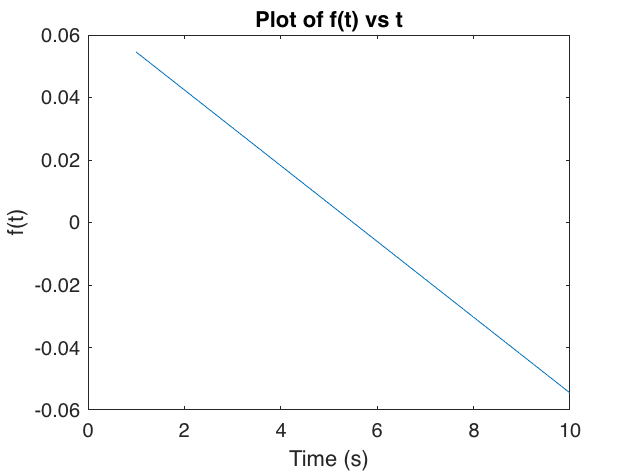

t = linspace(1,10,10);

figure
plot(t, p);
title('Plot of f(t) vs t');
xlabel('Time (s)');
ylabel('f(t)');

Plot x(t)

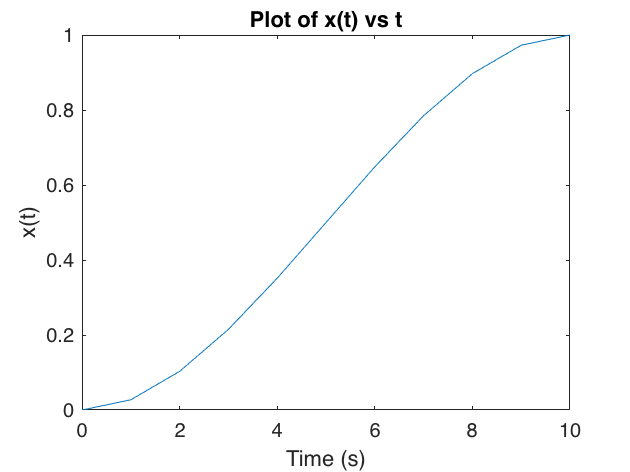

t = linspace(0, 10, 11);
x = zeros(11,2);
for i = 2:11
    x(i,:) = (A*x(i-1,:)'+b*p(i-1))';
end

figure
plot(t, x(:,1));
title('Plot of x(t) vs t');
xlabel('Time (s)');
ylabel('x(t)');

Plot x_dot(t)

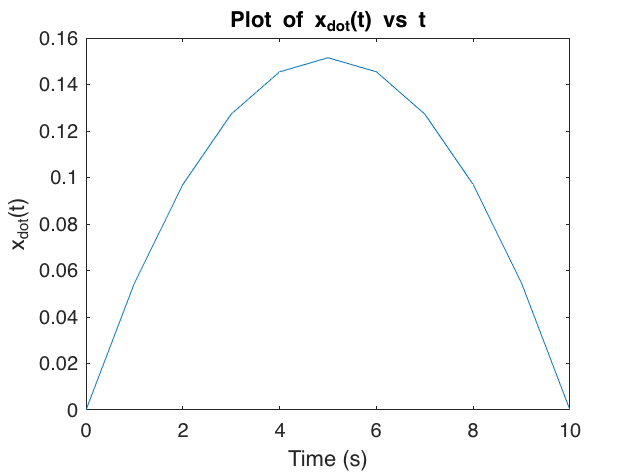

figure
plot(t, x(:,2));
title('Plot of x_{dot}(t) vs t');
xlabel('Time (s)');
ylabel('x_{dot}(t)');